# AFM Time-Lapse Image Processing with Phase Masking

This live script demonstrates loading, stacking, masking, and leveling AFM images from two time-lapse files using phase information.

## Step 1: Define File Paths and Channels

Update these file paths to your actual data locations

image_name1 = '/Folder/filename1';
image_name2 = '/Folder/filename2';

channel_phase = 'Lock-In Phase -Trace';  % Phase channel
channel_height = 'Height -Trace';        % Height channel

## Step 2: Load Phase Images and Visualise

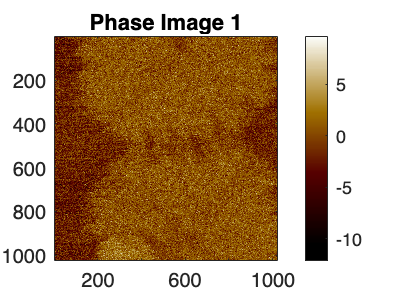

[im1_phase, ~] = ReadAFMFile(image_name1, channel_phase);
[im2_phase, ~] = ReadAFMFile(image_name2, channel_phase);

Img_phase = cat(3, im1_phase, im2_phase);

figure;
imagesc(im1_phase(:,:,1)); afm_colormap('AFM brown'); axis image; title('Phase Image 1'); colorbar;

## Step 3: Generate Mask from Phase Images

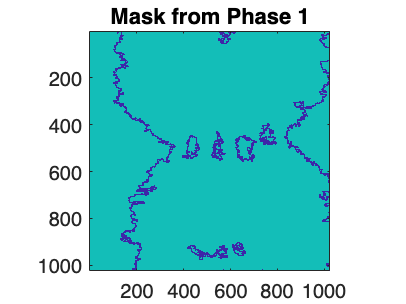

imgt = thresholder(Img_phase, 'otsu edges', [], 0);

figure;
imagesc(imgt(:,:,1)); axis image; title('Mask from Phase 1');

## Step 4: Load Height Images and Visualise

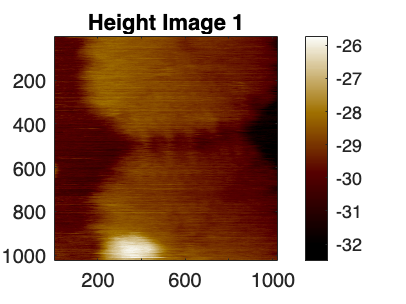

[im1_height, ImageInfo1] = ReadAFMFile(image_name1, channel_height);
[im2_height, ImageInfo2] = ReadAFMFile(image_name2, channel_height);

Img = cat(3, im1_height, im2_height);

figure;
imagesc(im1_height(:,:,1)); afm_colormap('AFM brown'); axis image; title('Height Image 1'); colorbar;

## Step 5: Apply Weighted Leveling to Each Frame

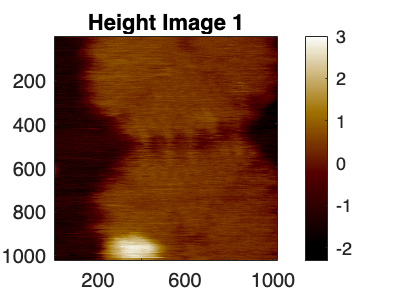

r = zeros(size(Img));

for i = 1:size(Img,3)
    temp = level_weighted(Img(:,:,i), 1, 1, 'plane', imgt(:,:,i));
    temp = level_weighted(temp, 0, 0, 'med_line', imgt(:,:,i));
    temp = level_weighted(temp, 1, 1, 'plane', imgt(:,:,i));
    temp = level_weighted(temp, 0, 0, 'med_line', imgt(:,:,i));
    r(:,:,i) = level(temp, 0, 0, 'mean_plane');
end

figure;
imagesc(r(:,:,1)); afm_colormap('AFM brown'); axis image; title('Height Image 1'); colorbar;

## Step 6: Store Processed Data into Structure Accessible by NanoLocz GUI

[~, name, ~] = fileparts(image_name1);

Data.ImageName = name;
Data.Channel = channel_height;
Data.Imagedata = r;

Data.ImageInfo = ImageInfo1;
Data.ImageInfo.n = ImageInfo1.n + ImageInfo2.n;
ImageInfo2.time = ImageInfo2.time + ImageInfo1.time(end);
Data.ImageInfo.time = [ImageInfo1.time, ImageInfo2.time];
Data.ImageInfo.ScanSize = [ImageInfo1.ScanSize, ImageInfo2.ScanSize];
Data.ImageInfo.PixelPerNm = [ImageInfo1.PixelPerNm, ImageInfo2.PixelPerNm];

Data.ImageLocs = [];
Data.ref = [];

disp('Processed AFM data stored in the "Data" structure.');

Processed AFM data stored in the "Data" structure.



%To open in NanoLocz GUI save the 'Data' Variable as a .mat file 
% For Example:
% filename = char("phase_leveled_image.mat"); 
% save(filename, 'Data');